## Part 1

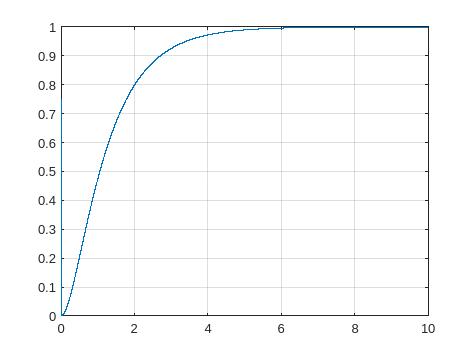

t = 0:0.001:10;
plot(t, 1 + exp(-3 * t) / 2 - 3 * exp(-t) / 2 .* heaviside(t));
grid on;

## Part2

ج

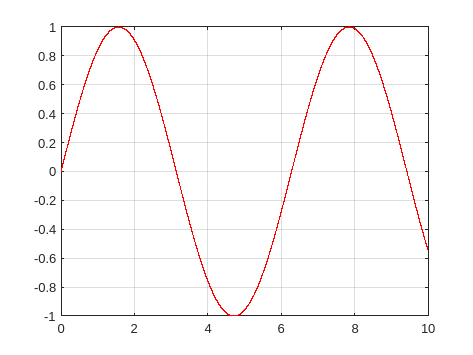

t = 0:0.001:10;
plot(t, sin(t), 'r');
grid on;

د

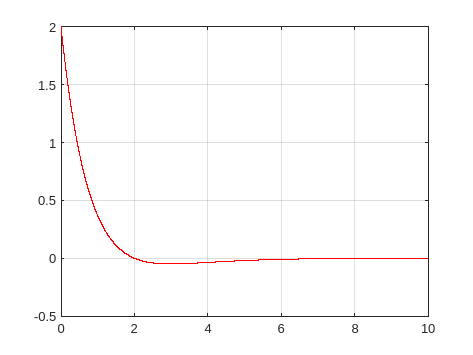

t = 0:0.001:10;
plot(t, 2.*exp(-t)-t.*exp(-t), 'r');
grid on;

و

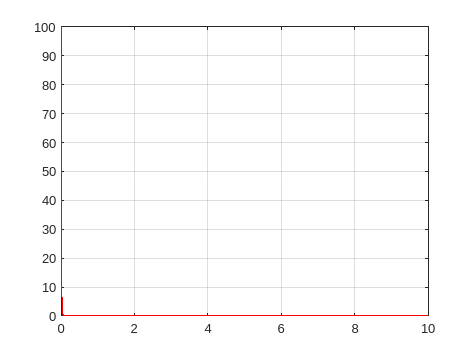

t = 0:0.001:10;
plot(t, 100.*exp(-100*t), 'r');
grid on;

## Part3

syms y(t) x(t) s Y
x(t) = 5 * heaviside(t);
y0 = 1;
dy0 = 1;
eqn = diff(y, t, 2) + 3 * diff(y, t) + 2 * y == x(t);
eqn_laplace = laplace(eqn, t, s);
eqn_laplace = subs(eqn_laplace, [laplace(y(t), t, s), y(0), subs(diff(y(t), t), t, 0)], [Y, y0, dy0]);
Y = solve(eqn_laplace, Y);
y_time = ilaplace(Y, s, t);
disp(y_time)

$$\frac{{\mathrm{e}}^{-2\,t}}{2}-2\,{\mathrm{e}}^{-t}+\frac{5}{2}$$

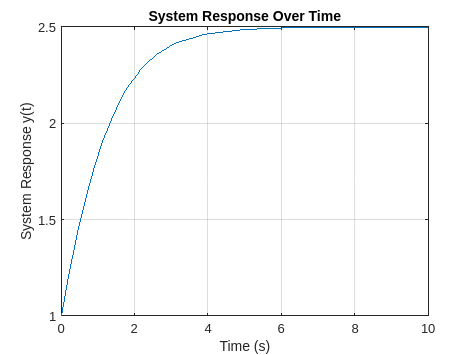

fplot(y_time, [0, 10]);
xlabel('Time (s)');
ylabel('System Response y(t)');
title('System Response Over Time');
grid on;